# Inputs

file_name_inp = 'mesh3D_quadratic2.inp'

file_name_inp = 'mesh3D_quadratic2.inp'

elemType = 'H10'

elemType = 'H10'

mesh_correction_type = 1

mesh_correction_type = 1

dim = 3

dim = 3

## Mesh from ABAQUS, read and update

[node, element, bdy_node, bdy_elem] = ps_read_mesh_abaqus(file_name_inp,elemType,mesh_correction_type)


## Plot the mesh

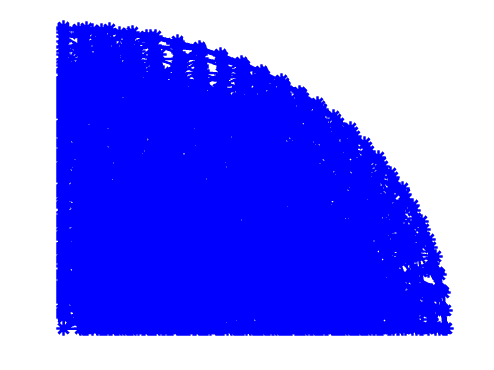

plot_mesh(node,element,elemType,'b*-')

ndof= size(node,1)    % number of nodes

ndof = 3579



% Adding node numbers as text at each node's location
if dim == 2
    for i = 1:ndof
        text(node(i, 1), node(i, 2), num2str(i), ...
            'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right', 'FontSize', 10, 'Color', 'r');
    end
elseif dim == 3
    for i = 1:ndof
        text(node(i, 1), node(i, 2),node(i,3), num2str(i), ...
            'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right', 'FontSize', 10, 'Color', 'r');
    end 
else
    warning('dimension not valid')
end



## Saving .png output file

% Save the figure as a .png file
saveas(gcf, '3D_quad_mesh1.png');